## **Econ 623: Computer Assignment 1**

## *Nond Prueksiri*

**Preparing Workspace**

clear;  
close all; 
clc;
cd('C:\Users\nprue\Desktop\econ623');
warning('off','all');

**Problem 1a**

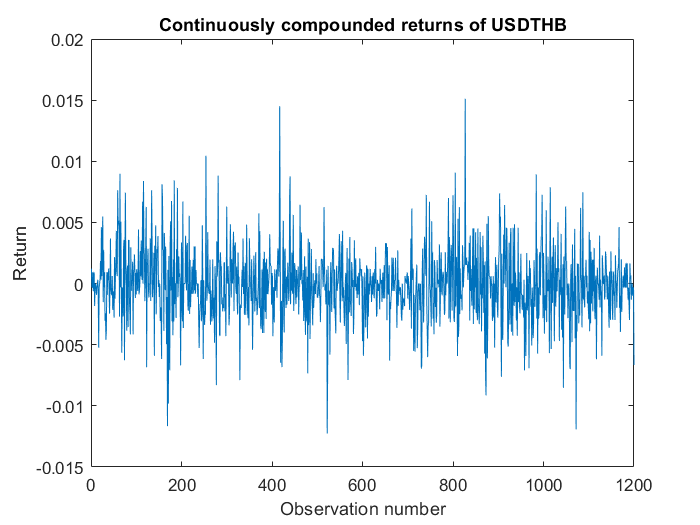

findata = csvread('findata.csv', 1,0);
findata(findata==0) = nan;
clean_dat = rmmissing(findata);
usdthb = clean_dat(:,2);
usdgold = clean_dat(:,3);

retthb = log(usdthb(2:end)./usdthb(1:end-1));
retgold = log(usdgold(2:end)./usdgold(1:end-1));

figure(1)
plot(retthb)
title('Continuously compounded returns of USDTHB')
xlabel('Observation number')
ylabel('Return')
xlim([0 1200])

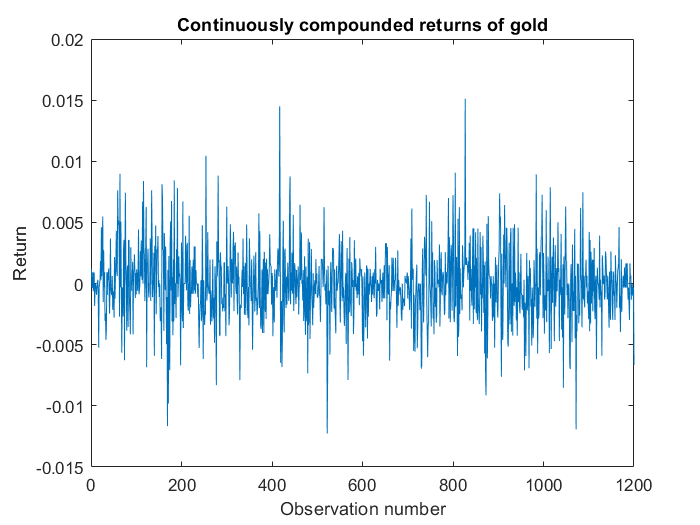

figure(2)
plot(retthb)
title('Continuously compounded returns of gold')
xlabel('Observation number')
ylabel('Return')
xlim([0 1200])

**Problem 1b**

% Function sum_stats.m
% ymean = mean(Y);
%      ymedian = median(Y);
%      ystd = std(Y);
%      ymax = max(Y);
%      ymin = min(Y);
%      yskew = skewness(Y);
%      ykurto = kurtosis(Y);
%     [~, JBp,JBt,~]  = jbtest(Y,[]);
%     label = ["Mean" "Median" "SD" "Max" "Min" "Skewness" "Kurtosis" "JB p-value" "JB t-stats"];
%     value = [ymean ymedian ystd ymax ymin yskew ykurto JBp JBt];
%     des_stat = vertcat(label, value);

**Descriptive Statistics for THB/USD**

desstat_thb = transpose(sum_stats(retthb))

desstat_thb = 9×2 string array
    "Mean"          "-5.234154e-05"
    "Median"        "0"            
    "SD"            "0.00293801"   
    "Max"           "0.01511675"   
    "Min"           "-0.0122596"   
    "Skewness"      "0.2541913"    
    "Kurtosis"      "5.34258"      
    "JB p-value"    "0.001"        
    "JB t-stats"    "291.377"      


**Descriptive Statistics for Gold Price**

desstat_thb = transpose(sum_stats(retgold))

desstat_thb = 9×2 string array
    "Mean"          "0.0001672253"
    "Median"        "0.0001978044"
    "SD"            "0.007851038" 
    "Max"           "0.03729693"  
    "Min"           "-0.04658322" 
    "Skewness"      "0.05225801"  
    "Kurtosis"      "5.118787"    
    "JB p-value"    "0.001"       
    "JB t-stats"    "228.1967"    


**Problem 2a **

model_a = fitlm(retgold, retthb)

model_a = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)    -3.2793e-05    8.0055e-05    -0.40963       0.68215
    x1                 -0.1169      0.010199     -11.462    5.9125e-29


Number of observations: 1217, Error degrees of freedom: 1215
Root Mean Squared Error: 0.00279
R-squared: 0.0976,  Adjusted R-Squared: 0.0968
F-statistic vs. constant model: 131, p-value = 5.91e-29

**Problem 2b**

Testing for $\beta_1 =1$

model_a.Coefficients

ans = 2×4 table
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)    -3.2793e-05    8.0055e-05    -0.40963       0.68215
    x1                 -0.1169      0.010199     -11.462    5.9125e-29


tstat = (table2array(model_a.Coefficients(2,"Estimate")) - 1)/table2array(model_a.Coefficients(2,"SE"));
abs(tstat) < norminv(0.975) 

ans = logical
   0


    The logical test reports that ans = 0 which means that the tstat is in the range of rejection region. We therefore reject the null hypothesis at 5% level of significance, that is, $\beta_1 \not= 1,$ or that continuously compounded return for USD/THB and gold does not have a proportionally positive association.

**Problem 2c **

X = [retgold(3:end) retgold(2:end-1) retgold(1:end-2)];
model_c = fitlm(X, retthb(3:end))

model_c = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)    -3.5453e-05    8.0158e-05    -0.44229       0.65836
    x1                -0.11763      0.010215     -11.515    3.4408e-29
    x2                0.018194      0.010205      1.7828      0.074865
    x3              -0.0032744       0.01021    -0.32072       0.74848


Number of observations: 1215, Error degrees of freedom: 1211
Root Mean Squared Error: 0.00279
R-squared: 0.1,  Adjusted R-Squared: 0.0981
F-statistic vs. constant model: 45, p-value = 1.36e-27

**Problem 2d **

The test takes from $R\beta =C$


$$\mathrm{Where}\;R=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \;,C=\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$$


varcov_c = model_c.CoefficientCovariance(2:4,2:4);
R1 = [1 0 0; 0 1 0; 0 0 1]

R1 =      1     0     0
     0     1     0
     0     0     1


beta_c = table2array(model_c.Coefficients(2:4,"Estimate"));
C = [0;0;0];
Chi2_c = (R1*beta_c - C)'*((R1'*varcov_c*R1)\(R1*beta_c - C));
Chi2_c < chi2inv(1-0.05, 3)

ans = logical
   0


    The logical test reports that ans = 0 which means that the chi-2 stst is in the range of rejection region. We therefore reject the null hypothesis, that is, joinly, there is at least one estimated coefficient that is significantly different from zero at 5% level of significance. 

**Problem 2e**

The test takes from $R\beta =C$


$$\mathrm{Where}\;R=\left\lbrack \begin{array}{ccc}
1 & -1 & 0\\
0 & 1 & -1\\
1 & 0 & -1
\end{array}\right\rbrack \;,C=\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$$


R2 = [1 -1 0; 0 1 -1; 1 0 -1];
Chi2_d = (R2*beta_c - C)'*((R2'*varcov_c*R2)\(R2*beta_c - C));
Chi2_d < chi2inv(1-0.05, 3)

ans = logical
   0


  The logical test reports that ans = 0 which means that the chi-2 stst is in the range of rejection region. We therefore reject the null hypothesis, that is, joinly, there is at least one pair of estimated coefficients that is significantly different from each other at 5% level of significance. 

**Problem 3a**

% function [Y] = arsim(T, sig2_eps, phi_0, phi_1)
%    Y = zeros(T, 1)
%    eps = normrnd(0, sqrt(sig2_eps), T, 1);
%    Y(1) = 0; <- Unconditional mean of AR(1) in the thoery
%    for t = 1:T-1
%        Y(t+1) = phi_0 + phi_1*Y(t) + eps(t);
%    end
% end

**Problem 3b**

Y = arsim(250,1,0,0.8);

Y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


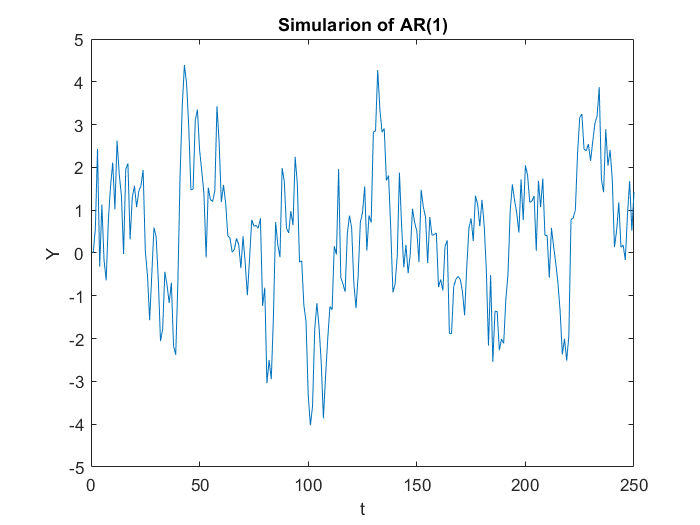

figure(3)
plot(Y)
title('Simularion of AR(1)')
xlabel('t')
ylabel('Y')
xlim([0 250])

**Problem 3c**

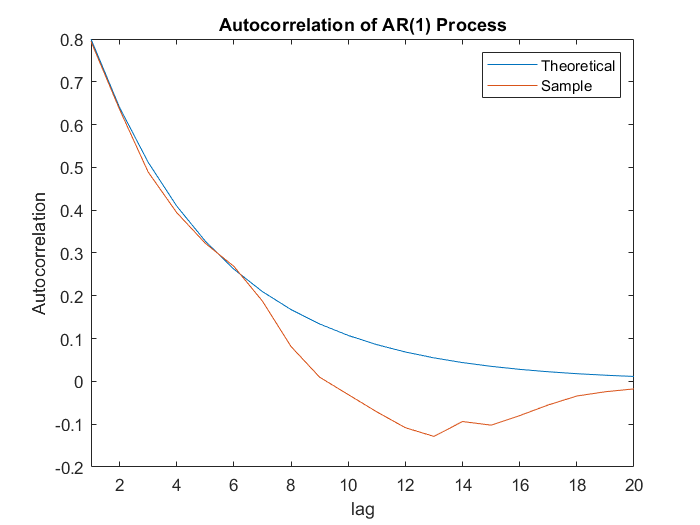

sam_corr = autocorr(Y);
theo_auto = zeros(20,1);
phi_1 = 0.8;

for i = 1:20
    theo_auto(i) = (phi_1)^i ; 
end

figure(4)
plot(theo_auto)
hold on
plot(sam_corr(2:21,:))
title('Autocorrelation of AR(1) Process')
xlabel('lag')
ylabel('Autocorrelation')
xlim([1 20])
legend('Theoretical','Sample') 

**Problem 4a**

%function [Y] = AR1simU(theta)
%    Y = zeros(theta(5), 1);
%    eps = theta(3)+ (theta(4)-theta(3)).*rand(theta(5),1);
%    Y(1) = 0;
%    for t = 1:(theta(5)-1)
%        Y(t+1) = theta(1) + theta(2)*Y(t) + eps(t);
%    end
% end

**Problem 4b**

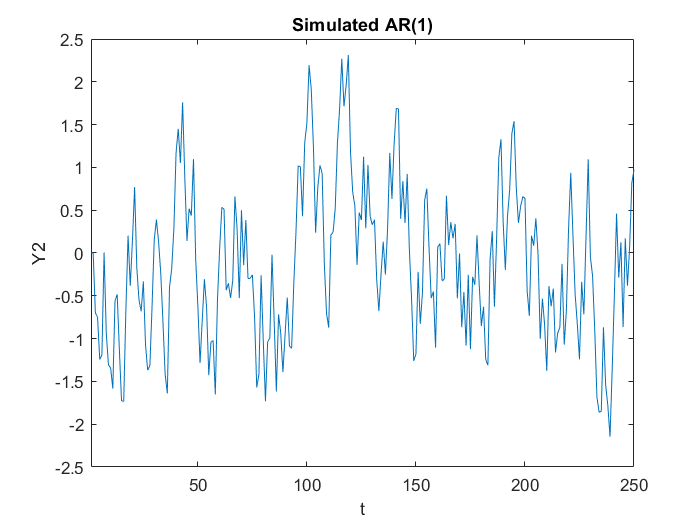

theta1 = [0 0.8 -1 1 250];
Y2 = AR1simU(theta1);
figure(5)
plot(Y2)
title('Simulated AR(1)')
xlabel('t')
ylabel('Y2')
xlim([1 250])

**Problem 4c**


$$E\left\lbrack X_t \left|\phi_0 \;,\phi_1 ,L,U\;\right.\right\rbrack =\frac{\phi_0 +\frac{L+U}{2}}{1-\phi_1 }$$


**Problem 4d**

%function [outmean] = AR1meanU(phi_0, phi_1,L, U)
%     outmean = (phi_0 + 0.5*(L+U)) / (1-phi_1);
%end

mean_compare = zeros(3,3);

theta_i = [0,0.8,-1,1,100000];
mean_compare(1,1) = mean(AR1simU(theta_i));
mean_compare(1,2) = AR1meanU(0,0.8,-1,1);

theta_ii = [0,0.8,-2,1,100000];
mean_compare(2,1) = mean(AR1simU(theta_ii));
mean_compare(2,2) = AR1meanU(0,0.8,-2,1);

theta_iii = [1,0.8,-5,2,100000];
mean_compare(3,1) = mean(AR1simU(theta_iii));
mean_compare(3,2) = AR1meanU(1,0.8,-5,2);

mean_compare(:,3) = mean_compare(:,2) - mean_compare(:,1);
labelmean = ["sample" "analytical" "difference"];
vertcat(labelmean, mean_compare)

ans = 4×3 string array
    "sample"         "analytical"    "difference"
    "-0.00058077"    "0"             "0.00058077"
    "-2.4971"        "-2.5"          "-0.002878" 
    "-2.4783"        "-2.5"          "-0.021734" 
